recordFile = "../data/type1/76/H60-L01_to_AUM-AL20.wav";
% recordFile = "../data/type1/77/AUM-AL20_to_H60-L01.wav";
samplingRate = 44100;
fBegin = 2000;
fEnd = 6000;
chirpTimeMs = 100;
device1D = 0.01;
device2D = 0.01;
soundSpeed = 340;

## 原始信号

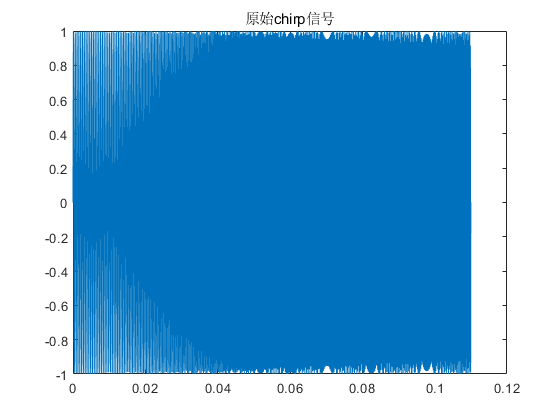

[originChirpT, originChirpY] = generateChirp(samplingRate,fBegin, fEnd, chirpTimeMs, 10);
%% 时域处理
plot(originChirpT, originChirpY);
title("原始chirp信号")

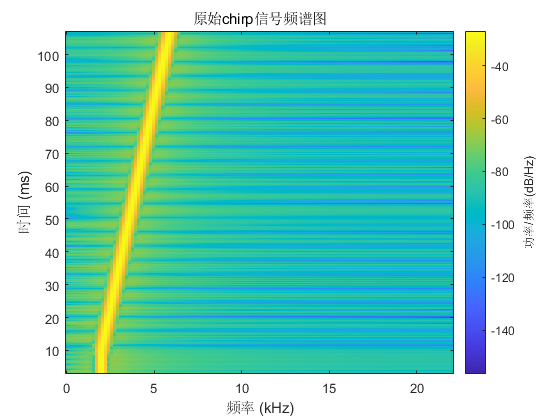

spectrogram(originChirpY, 256, 250, 256, samplingRate);
title("原始chirp信号频谱图")

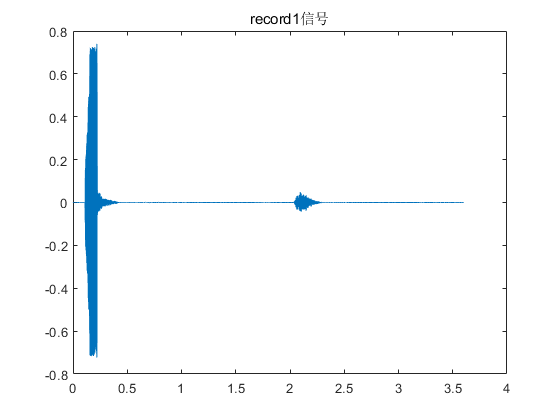


% 由于录音问题，舍弃前0.1秒的数据
[recordY, recordFs] = audioread(recordFile);
recordY = recordY(floor(0.1 * samplingRate):length(recordY));
recordLen = length(recordY);
%% 时域处理
recordT = (0:recordLen-1)/recordFs;
plot(recordT, recordY);
title("record1信号");

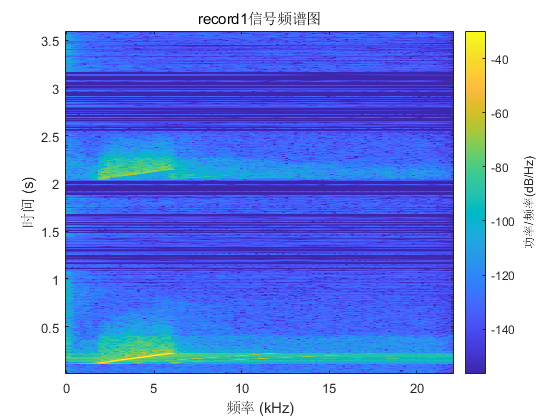

spectrogram(recordY, 256, 250, 256, samplingRate);
title("record1信号频谱图");

## 互相关

% 
% [c,lags] = xcorr(recordY, originChirpY)
% stem(lags / samplingRate, c)
% 
% radius = 20000; % 辅助区间的半径
% [~, maxIndex1] = max(c);
% rangeStart1 = maxIndex1 - radius
% rangeEnd1 = maxIndex1 + radius;
% % stem(lags,c);
% tmp = [c(1:rangeStart1 - 1); zeros(radius * 2 + 1, 1); c(rangeEnd1 + 1:length(c))]
% % stem(lags, tmp);
% [~, maxIndex2] = max(tmp);
% if maxIndex1 < maxIndex2
%     cutPoint = maxIndex2 - radius
% else
%     cutPoint = maxIndex1 - radius
% end
% 
% plot(recordT(1:cutPoint-1-recordLen),recordY(1:cutPoint-1-recordLen))
% title("第一段")
% plot(recordT(cutPoint-recordLen:recordLen),recordY(cutPoint-recordLen:recordLen))
% title("第二段")
% 
% peakRadius = 1000;
% 
% % 处理第一段
% tmpRecord = recordY(1:cutPoint-1-recordLen);
% tmpRecordLen = length(tmpRecord);
% % 扩展原始chirp信号
% originChirpExtend = [originChirpY, zeros(1, tmpRecordLen - length(originChirpY))]
% plot([1:length(originChirpExtend)] / samplingRate, originChirpExtend)
% [~, R, gccLags] = gccphat(tmpRecord, originChirpExtend', 44100);
% gccphat(tmpRecord, originChirpExtend', 44100)
% c = abs(R)
% stem(gccLags, c);
% title({recordFile, "第一处峰值"}, 'Interpreter', 'none')
% xlabel("时延")
% [~, maxIndex] = max(c);
% stem(gccLags(maxIndex-peakRadius:maxIndex+peakRadius), c(maxIndex-peakRadius:maxIndex+peakRadius))
% title({recordFile, "第一处峰值局部放大"}, 'Interpreter', 'none')
% xlabel("时延")
% 
% t1 = gccLags(maxIndex, 1)
% 
% 
% 
% % 处理第二段
% tmpRecord = recordY(cutPoint-recordLen:recordLen);
% tmpRecordLen = length(tmpRecord);
% % 扩展原始chirp信号
% originChirpExtend = [originChirpY, zeros(1, tmpRecordLen - length(originChirpY))]
% [~, R, gccLags] = gccphat(tmpRecord, originChirpExtend', 44100);
% c = abs(R)
% stem(gccLags, c);
% title({recordFile, "第二处峰值"}, 'Interpreter', 'none')
% xlabel("时延")
% [~, maxIndex] = max(c);
% stem(gccLags(maxIndex-peakRadius:maxIndex+peakRadius), c(maxIndex-peakRadius:maxIndex+peakRadius))
% title({recordFile, "第二处峰值局部放大"}, 'Interpreter', 'none')
% xlabel("时延")


% 先利用互相关辅助将信号分割成两段
% 新函数

[c,lags] = xcorr(recordY, originChirpY)

c = 	1.0e+03 *

   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


lags =      -158760     -158759     -158758     -158757     -158756     -158755     -158754     -158753     -158752     -158751     -158750     -158749     -158748     -158747     -158746     -158745     -158744     -158743     -158742     -158741     -158740     -158739     -158738     -158737     -158736     -158735     -158734     -158733     -158732     -158731     -158730     -158729     -158728     -158727     -158726     -158725     -158724     -158723     -158722     -158721     -158720     -158719     -158718     -158717     -158716     -158715     -158714     -158713     -158712     -158711


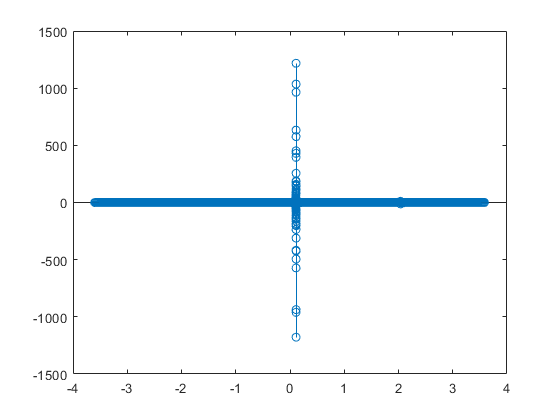

stem(lags / samplingRate, c)


radius = 20000; % 辅助区间的半径
[~, maxIndex1] = max(c);
rangeStart1 = maxIndex1 - radius

rangeStart1 = 143690

rangeEnd1 = maxIndex1 + radius;
% stem(lags,c);
tmp = [c(1:rangeStart1 - 1); zeros(radius * 2 + 1, 1); c(rangeEnd1 + 1:length(c))]

tmp =    -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


% stem(lags, tmp);
[~, maxIndex2] = max(tmp);
if maxIndex1 < maxIndex2
    cutPoint = maxIndex2 - radius
else
    cutPoint = maxIndex1 - radius
end

cutPoint = 229100

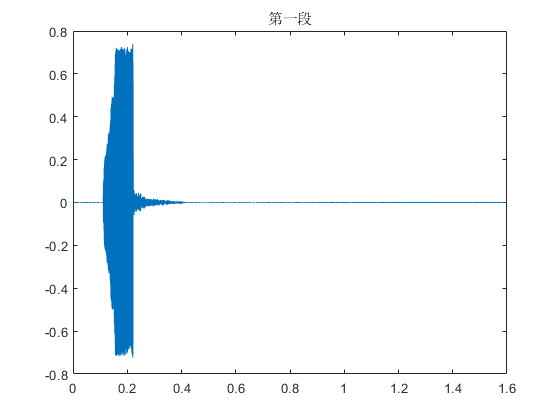


plot(recordT(1:cutPoint-1-recordLen),recordY(1:cutPoint-1-recordLen))
title("第一段")

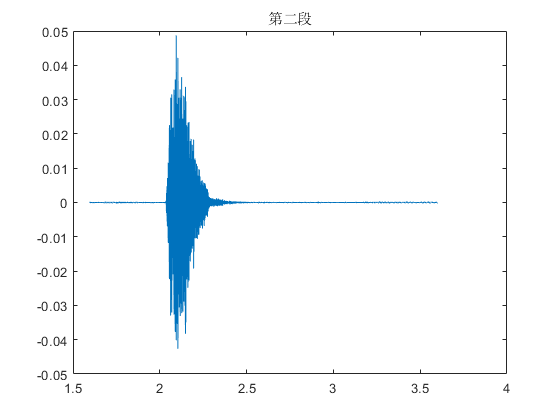

plot(recordT(cutPoint-recordLen:recordLen),recordY(cutPoint-recordLen:recordLen))
title("第二段")


peakRadius = 1000;

% 处理第一段
tmpRecord = recordY(1:cutPoint-1-recordLen);
tmpRecordLen = length(tmpRecord);
% 扩展原始chirp信号
originChirpExtend = [originChirpY, zeros(1, tmpRecordLen - length(originChirpY))]

originChirpExtend =          0    0.2811    0.5396    0.7545    0.9086    0.9894    0.9904    0.9115    0.7591    0.5455    0.2879    0.0071   -0.2743   -0.5335   -0.7498   -0.9056   -0.9883   -0.9913   -0.9144   -0.7638   -0.5515   -0.2948   -0.0142    0.2674    0.5275    0.7450    0.9025    0.9872    0.9922    0.9173    0.7683    0.5574    0.3016    0.0214   -0.2605   -0.5214   -0.7403   -0.8994   -0.9860   -0.9931   -0.9201   -0.7729   -0.5633   -0.3083   -0.0285    0.2537    0.5153    0.7355    0.8963    0.9848


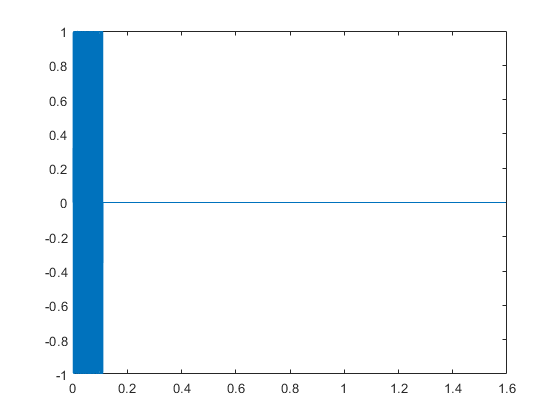

plot([1:length(originChirpExtend)] / samplingRate, originChirpExtend)

[R, gccLags] = MyGCC(tmpRecord, originChirpExtend', 44100, 2000, 4000);
% gccphat(tmpRecord, originChirpExtend', 44100)
c = abs(R)

c =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


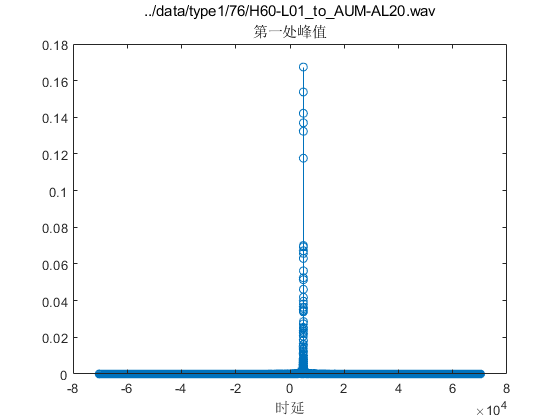

stem(gccLags, c);
title({recordFile, "第一处峰值"}, 'Interpreter', 'none')
xlabel("时延")

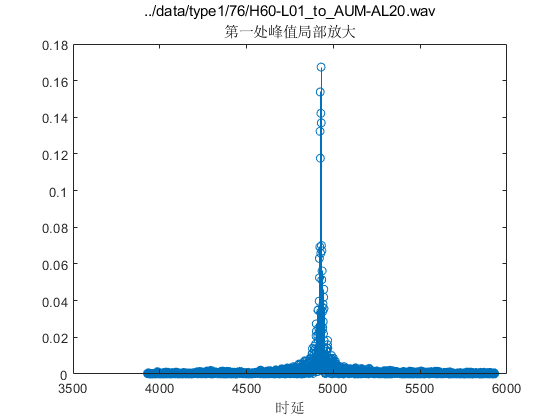

[~, maxIndex] = max(c);
stem(gccLags(maxIndex-peakRadius:maxIndex+peakRadius), c(maxIndex-peakRadius:maxIndex+peakRadius))
title({recordFile, "第一处峰值局部放大"}, 'Interpreter', 'none')
xlabel("时延")


t1 = gccLags(1, maxIndex)

t1 = 4929






% 处理第二段
tmpRecord = recordY(cutPoint-recordLen:recordLen);
tmpRecordLen = length(tmpRecord);
% 扩展原始chirp信号
originChirpExtend = [originChirpY, zeros(1, tmpRecordLen - length(originChirpY))]

originChirpExtend =          0    0.2811    0.5396    0.7545    0.9086    0.9894    0.9904    0.9115    0.7591    0.5455    0.2879    0.0071   -0.2743   -0.5335   -0.7498   -0.9056   -0.9883   -0.9913   -0.9144   -0.7638   -0.5515   -0.2948   -0.0142    0.2674    0.5275    0.7450    0.9025    0.9872    0.9922    0.9173    0.7683    0.5574    0.3016    0.0214   -0.2605   -0.5214   -0.7403   -0.8994   -0.9860   -0.9931   -0.9201   -0.7729   -0.5633   -0.3083   -0.0285    0.2537    0.5153    0.7355    0.8963    0.9848


[R, gccLags] = MyGCC(tmpRecord, originChirpExtend', 44100, 2000, 4000);
c = abs(R)

c =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


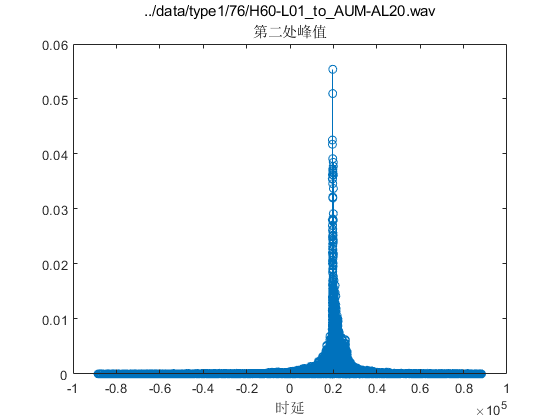

stem(gccLags, c);
title({recordFile, "第二处峰值"}, 'Interpreter', 'none')
xlabel("时延")

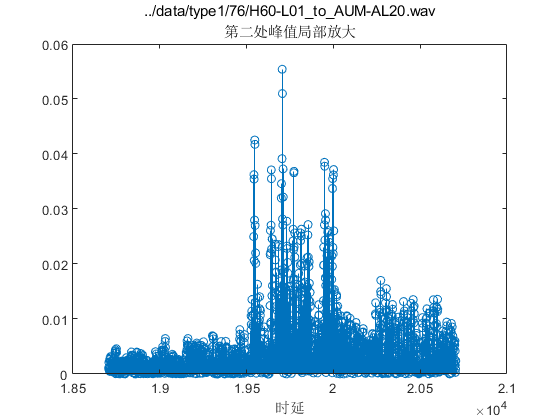

[~, maxIndex] = max(c);
stem(gccLags(maxIndex-peakRadius:maxIndex+peakRadius), c(maxIndex-peakRadius:maxIndex+peakRadius))
title({recordFile, "第二处峰值局部放大"}, 'Interpreter', 'none')
xlabel("时延")

## 计算距离

% [path, name, ext] = fileparts(recordFile1)
%  path + "/" + name + "_"
% % [recordY, recordFs] = audioread(recordFile);
% % td1 = computeTimeDifference(recordY, originChirpY, samplingRate)
% % [recordY, recordFs] = audioread(recordFile2);
% % td2 = computeTimeDifference(recordY, originChirpY, samplingRate)
% % D = abs(td1 - td2) * soundSpeed / 2 + (device1D + device2D) / 2
%
% computeDistance(recordFile1, recordFile2, device1D, device2D, samplingRate, fBegin, fEnd, chirpTimeMs, soundSpeed)